clearvars
syms theta h u d1u d2u d3u d4u f d1f d2f
Un_pls_1 = Teilor2(h,u,d1u,d2u,d3u);
Un = u;
Un_min_1 = Teilor2(-h,u,d1u,d2u,d3u);
fn_pls_1 = Teilor(h,d1u,d2u,d3u);
fn_min_1 = Teilor(-h,d1u,d2u,d3u);

eq = Un_pls_1 + (theta - 2)* Un + (1-theta)*Un_min_1 - 1/4 *h*((6+theta)*fn_pls_1 + 3 *(theta-2)*fn_min_1);
simplify(eq)

$$ans = -\frac{h^{2}\,\left(6\,\mathrm{d2u}+\mathrm{d3u}\,h\,\theta \right)}{3}$$


U = zeros(2,2);% it is current position of both points 
% format raw = [x_j,y_j]' where j is time; column is point number

U(:,1) = [-0.5,0];
U(:,2) = [0.5,0];

N = 100;% including t=0, and t=1 points
h = 1/(N-1);

time =(0:h:1);

U1_evalution = zeros(2,N); %there are point #1 evolution 
% every colomn is in format [x_j,y_j]' where j is time
U2_evalution = zeros(2,N);
U1_evalution(:,1) = U(:,1);
U2_evalution(:,1) = U(:,2);

for i = (2:N)
    U = ExpEuler(U,h,@fun);
    %U = RK3(U,h,@fun); for last task if you want to look at RungeKutta solution
    %unlock it and lock ExpEuler

    U1_evalution(:,i) = U(:,1);
    U2_evalution(:,i) = U(:,2);
end


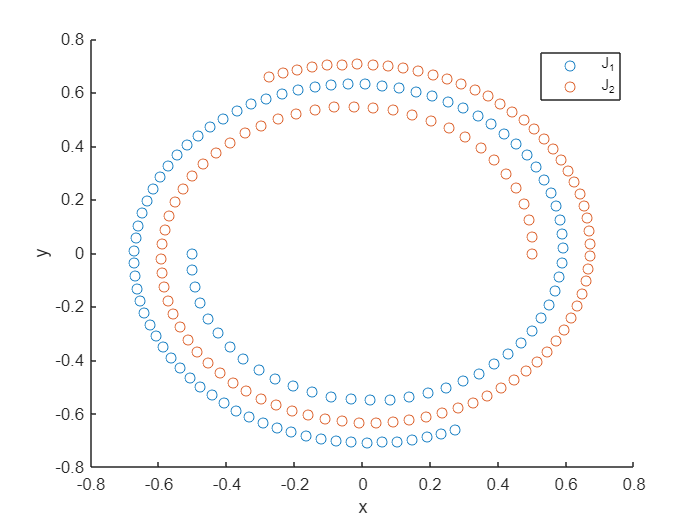

scatter(U1_evalution(1,:),U1_evalution(2,:));
hold on
scatter(U2_evalution(1,:),U2_evalution(2,:));
legend("J_1","J_2");
xlabel("x")
ylabel("y")
hold off

% Errors calculation
Ns = 2.^ (4:15);

Er1 = zeros(size(Ns));
Er2 = zeros(size(Ns));
j = 1;
for N = Ns
    U = zeros(2,2);% it is current position of both points 
    % format raw = [x_j,y_j]' where j is time; column is point number
    
    U(:,1) = [-0.5,0];
    U(:,2) = [0.5,0];
    
    
    h = 1/(N-1);
    
    time =(0:h:1);
    
    U1_evalution = zeros(2,N); %there are point #1 evolution 
    % every colomn is in format [x_j,y_j]' where j is time
    U2_evalution = zeros(2,N);
    U1_evalution(:,1) = U(:,1);
    U2_evalution(:,1) = U(:,2);
    
    for i = (2:N)
        U = ExpEuler(U,h,@fun);
    
        U1_evalution(:,i) = U(:,1);
        U2_evalution(:,i) = U(:,2);
    end

    Er1(j) = norm(U1_evalution(:,end) - U1_evalution(:,1));
    Er2(j) = norm(U2_evalution(:,end) - U2_evalution(:,1));
    j =j+1;
end

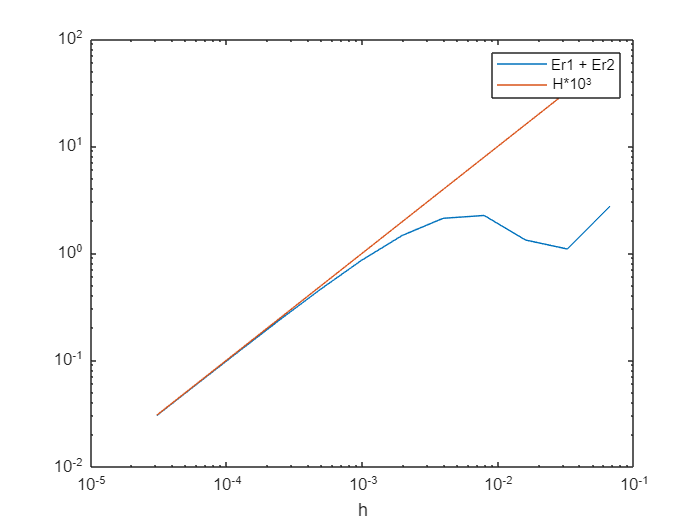

H = 1./(Ns - 1);
loglog(H,Er1+Er2);
hold on
loglog(H,H*10^3);
legend("Er1 + Er2","H*10^3")
xlabel("h")
hold off

% Errors calculation
Ns = 2.^ (4:15);

Er1 = zeros(size(Ns));
Er2 = zeros(size(Ns));
j = 1;
for N = Ns
    U = zeros(2,2);% it is current position of both points 
    % format raw = [x_j,y_j]' where j is time; column is point number
    
    U(:,1) = [-0.5,0];
    U(:,2) = [0.5,0];
    
    
    h = 1/(N-1);
    
    time =(0:h:1);
    
    U1_evalution = zeros(2,N); %there are point #1 evolution 
    % every colomn is in format [x_j,y_j]' where j is time
    U2_evalution = zeros(2,N);
    U1_evalution(:,1) = U(:,1);
    U2_evalution(:,1) = U(:,2);
    
    for i = (2:N)
        U = RK3(U,h,@fun);% only modification
    
        U1_evalution(:,i) = U(:,1);
        U2_evalution(:,i) = U(:,2);
    end

    Er1(j) = norm(U1_evalution(:,end) - U1_evalution(:,1));
    Er2(j) = norm(U2_evalution(:,end) - U2_evalution(:,1));
    j =j+1;
end

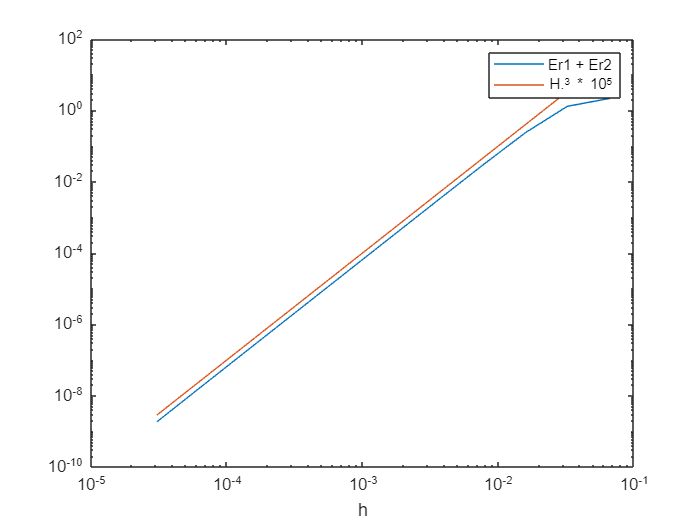

H = 1./(Ns - 1);
loglog(H,Er1+Er2);
hold on
loglog(H,H.^3*10^5);
legend("Er1 + Er2","H.^3 * 10^5")
xlabel("h")
hold off

function res = RK3(U,h,fun)
    k1_point1 = U(:,1) + h*fun(U(:,1),U(:,2));
    k1_point2 = U(:,2) + h*fun(U(:,2),U(:,1));
    
    
    k2_point1 = 3/4 *U(:,1) + 1/4 * k1_point1 + 1/4 *h *fun(k1_point1,k1_point2);
    k2_point2 = 3/4 *U(:,2) + 1/4 * k1_point2 + 1/4 *h *fun(k1_point2,k1_point1);

    Unext_p1 = 1/3 *U(:,1) + 2/3 *k2_point1 + 2/3 * h * fun(k2_point1,k2_point2);
    Unext_p2 = 1/3 *U(:,2) + 2/3 *k2_point2 + 2/3 * h * fun(k2_point2,k2_point1);
    
    res = [Unext_p1,Unext_p2];
end

function res = ExpEuler(un,h,fun)
    U1 = un(:,1) + h* fun(un(:,1),un(:,2));
    U2 = un(:,2) + h* fun(un(:,2),un(:,1));
    res = [U1,U2];
end

function res = fun(Point,Point2)
    dP = Point-Point2;
    dx = dP(1);
    dy = dP(2);

    G = 4* pi^2;

    Unx = -(G/(2*pi) *dy/(dx^2 +dy^2));
    Uny = (G/(2*pi) *dx/(dx^2 +dy^2));
    res = [Unx,Uny]';
end

function res = Teilor2(h,u,du,ddu,dddu)
    res = u + h*du + h^2 /2 *ddu+ h^3/6 * dddu;% + h^4/24 * ddddu;
end
function res = Teilor(h,u,du,ddu)
    res = u + h*du + h^2 /2 *ddu; % h^3/6 * dddu + h^4/24 * ddddu;
end